Function

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx)

yy =     0.2000    0.3893    0.5546    0.6978    0.8209    0.9258    1.0140    1.0874    1.1474    1.1956    1.2334    1.2621    1.2829    1.2972    1.3059    1.3101    1.3108    1.3090    1.3054    1.3008    1.2960    1.2915    1.2881    1.2862    1.2863    1.2889    1.2943    1.3029    1.3148    1.3305    1.3500    1.3735    1.4010    1.4327    1.4686    1.5086    1.5527    1.6007    1.6527    1.7083    1.7675    1.8300    1.8956    1.9640    2.0349    2.1081    2.1832    2.2598    2.3377    2.4164


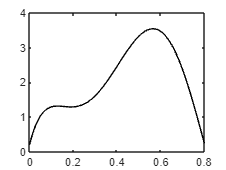

plot(xx,yy,'k-')
axis([0 0.8 0 4])

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000


q = polyint(p)

q =    66.6667 -180.0000  168.7500  -66.6667   12.5000    0.2000         0



Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with trapezoidal rule ns = 1

ns = 1;

x = linspace(0, 0.8, ns+1)

x =          0    0.8000


y = f(x)

y =     0.2000    0.2320


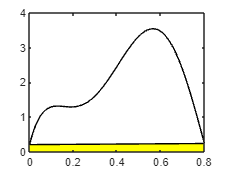



area(x,y,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(xx,yy,'k-')
hold off
axis([0 0.8 0 4])



p = polyfit(x,y,1)

p =     0.0400    0.2000


q = polyint(p)

q =     0.0200    0.2000         0


I1 = diff(polyval(q, [a b]))

I1 = 0.1728

et = (Itrue - I1)/Itrue*100

et = 89.4668

Plot original function along with trapezoidal rule ns = 4

ns = 4;

x = linspace(0, 0.8, ns+1)

x =          0    0.2000    0.4000    0.6000    0.8000


y = f(x)

y =     0.2000    1.2880    2.4560    3.4640    0.2320



figure
color = ['g','y']

color = 'gy'

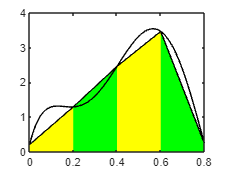

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
end

plot(xx,yy,'k-')
hold off
axis([0 0.8 0 4])


I4 = trap(f,a,b,4)

I4 = 1.4848

et4 = (Itrue - I4)/Itrue*100

et4 = 9.4928

| et | < 1

I5 = trap(f,a,b,13)

I5 = 1.6228

et4 = (Itrue - I5)/Itrue*100

et4 = 1.0804